input.main_dir = '/Volumes/spacetop_projects_cue';
input.glm_dir = fullfile(input.main_dir, '/analysis/fmri/spm/univariate/model01_6cond/1stLevel');
input.glm_modelname = "6conditions";
input.smooth_dir = fullfile(input.main_dir,"/analysis/fmri/smooth6mm");
input.fmriprep_dir = "/Volumes/fmriprep/results/fmriprep";
input.output_dir = fullfile(input.main_dir, '/analysis/fmri/spm/univariate/model01_6cond/vif');
input.sub_id = 'sub-0061'

input = struct with fields:
         main_dir: '/Volumes/spacetop_projects_cue'
          glm_dir: '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel'
    glm_modelname: "6conditions"
       smooth_dir: "/Volumes/spacetop_projects_cue/analysis/fmri/smooth6mm"
     fmriprep_dir: "/Volumes/fmriprep/results/fmriprep"
       output_dir: '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/vif'
           sub_id: 'sub-0061'



vif_calc(input);


main_dir = input.main_dir;
glm_dir = input.glm_dir;
glm_modelname = input.glm_modelname;
fmriprep_dir = input.fmriprep_dir;
smooth_dir = input.smooth_dir;
output_dir = fullfile(input.output_dir, input.sub_id);

if not(exist(input.output_dir, 'dir'))
    mkdir(input.output_dir)
end
sub = input.sub_id;
disp(strcat("vif_calc:", sub));

vif_calc:sub-0061


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.



VIFs greater than 1.300000e+00

    VIF   REGRESSOR
   1.35   reg0003: "Sn(1) cue-high_stim-low*bf(1)"
   1.47   reg0007: "Sn(1) CUE*bf(1)"
   1.55   reg0008: "Sn(1) EXPECT_RATING*bf(1)"
   4.44   reg0010: "Sn(1) R1"
  15.56   reg0011: "Sn(1) R2"
   1.67   reg0012: "Sn(1) R3"
   2.26   reg0013: "Sn(1) R4"
 116.59   reg0015: "Sn(1) R6"
   1.82   reg0016: "Sn(1) R7"
   1.46   reg0017: "Sn(1) R8"
  92.40   reg0018: "Sn(1) R9"
  11.43   reg0019: "Sn(1) R10"
   2.16   reg0020: "Sn(1) R11"
   2.36   reg0021: "Sn(1) R12"
   3.12   reg0022: "Sn(1) R13"
 111.97   reg0023: "Sn(1) R14"
   1.73   reg0024: "Sn(1) R15"
   1.91   reg0025: "Sn(1) R16"
  71.11   reg0026: "Sn(1) R17"
  71.21   reg0027: "Sn(1) R18"
   1.52   reg0028: "Sn(1) R19"
  49.28   reg0030: "Sn(1) R21"
  73.09   reg0031: "Sn(1) R22"
   1.33   reg0032: "Sn(1) R23"
   1.40   reg0033: "Sn(1) R24"
  30.24   reg0034: "Sn(1) R25"
   1.86   reg0035: "Sn(1) R26"
   1.44   reg0043: "Sn(1) R34"
   1.45   reg0052: "Sn(2) CUE*bf(1)"
   1.46 

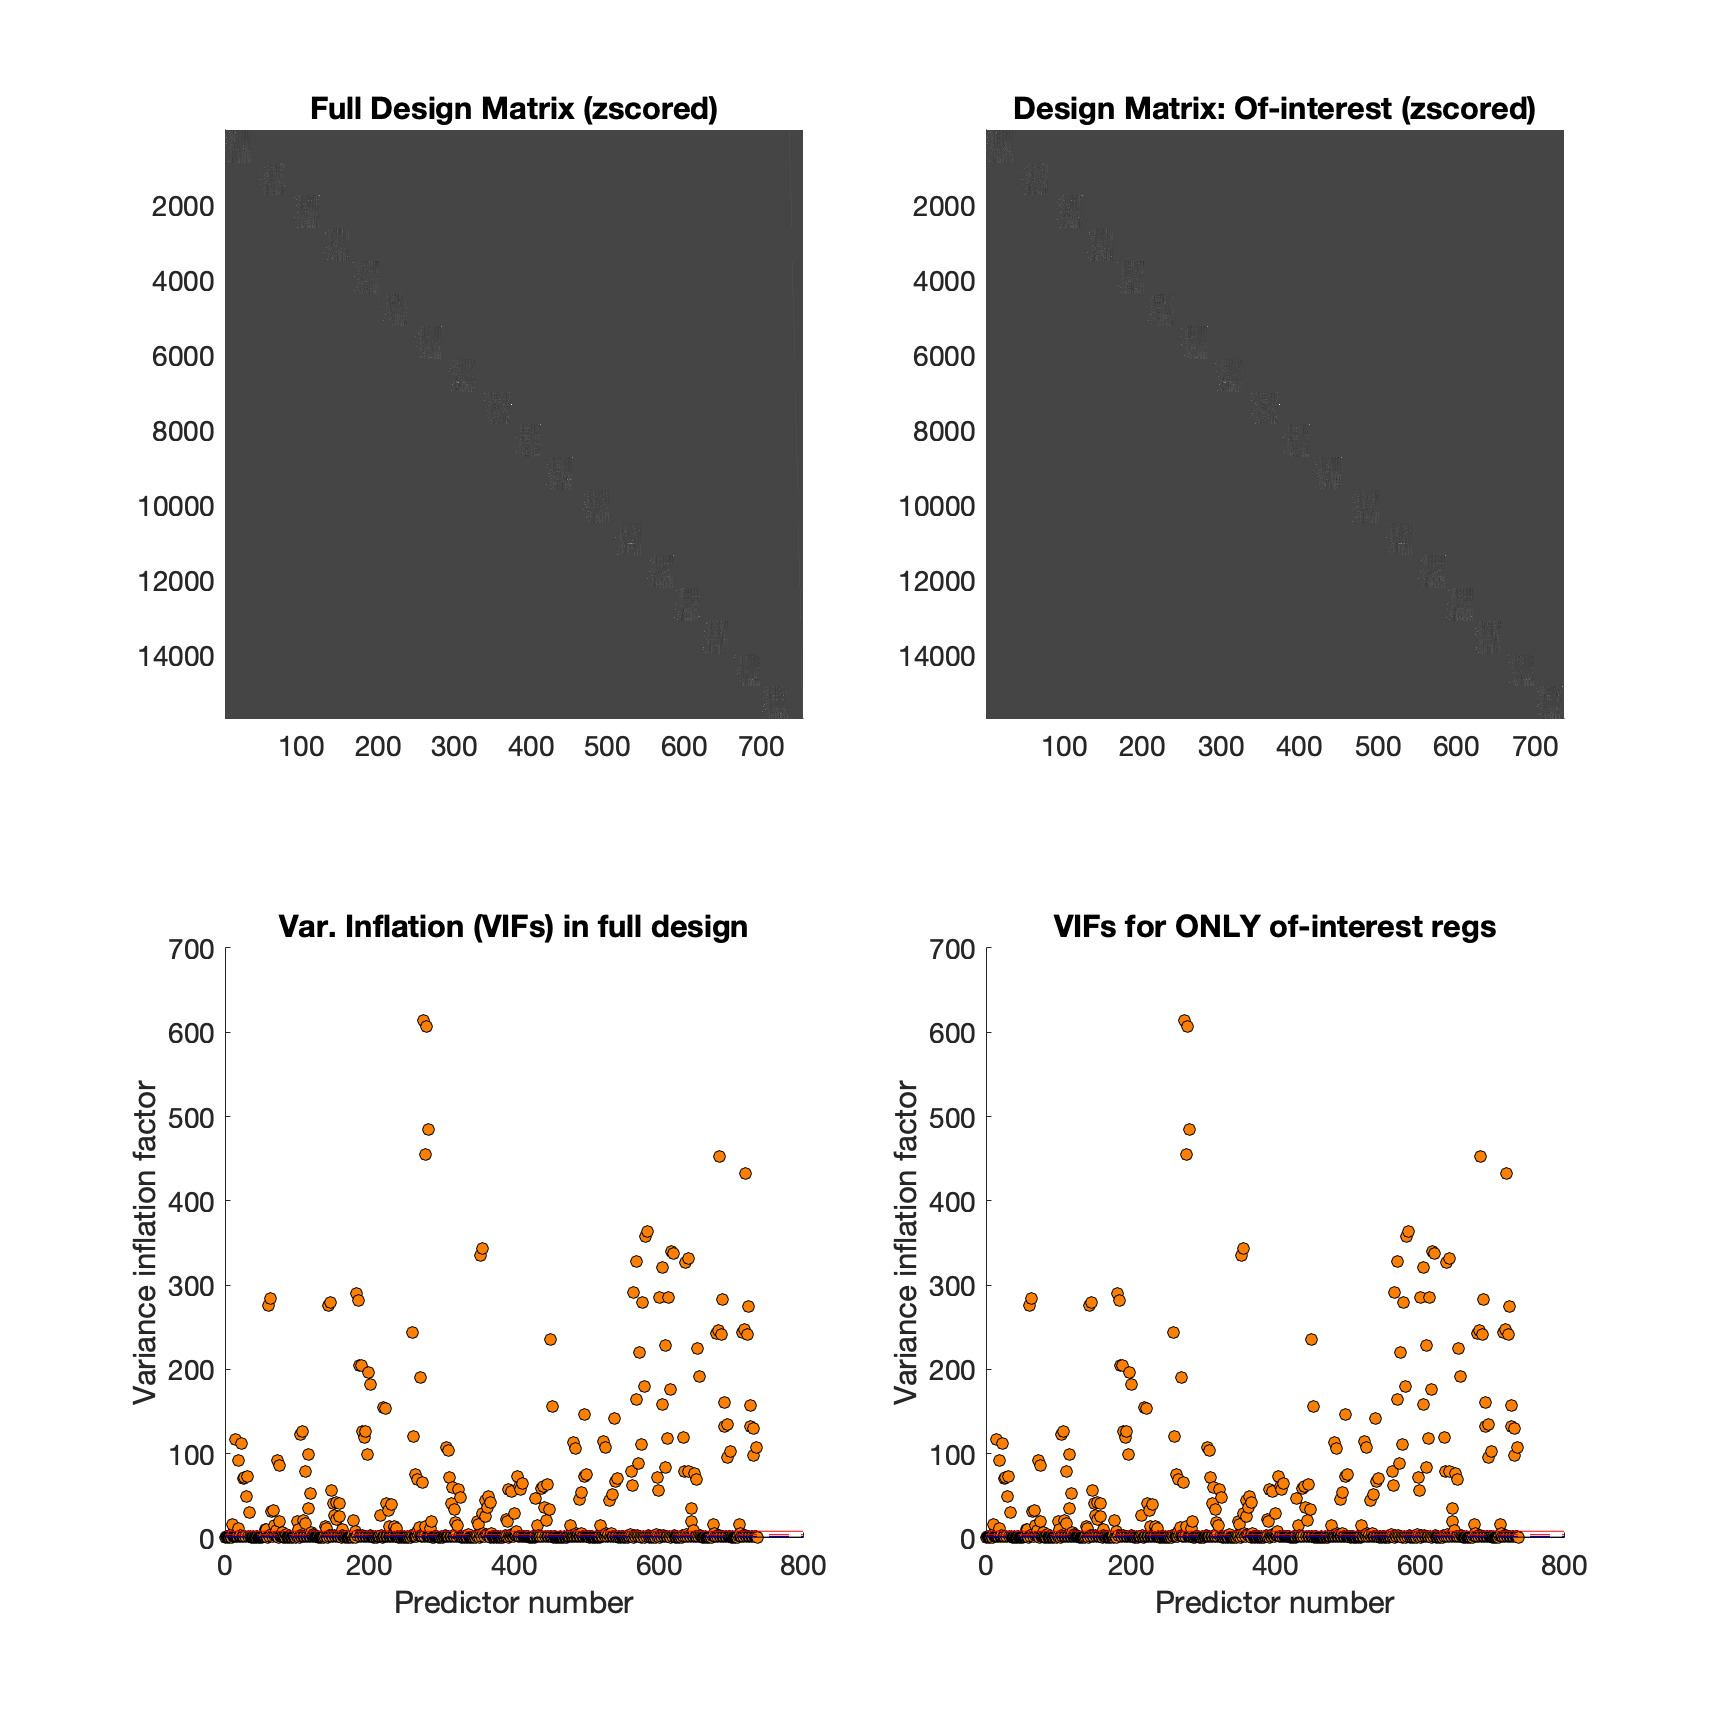

Saved Variance_Inflation.png in SPM directory


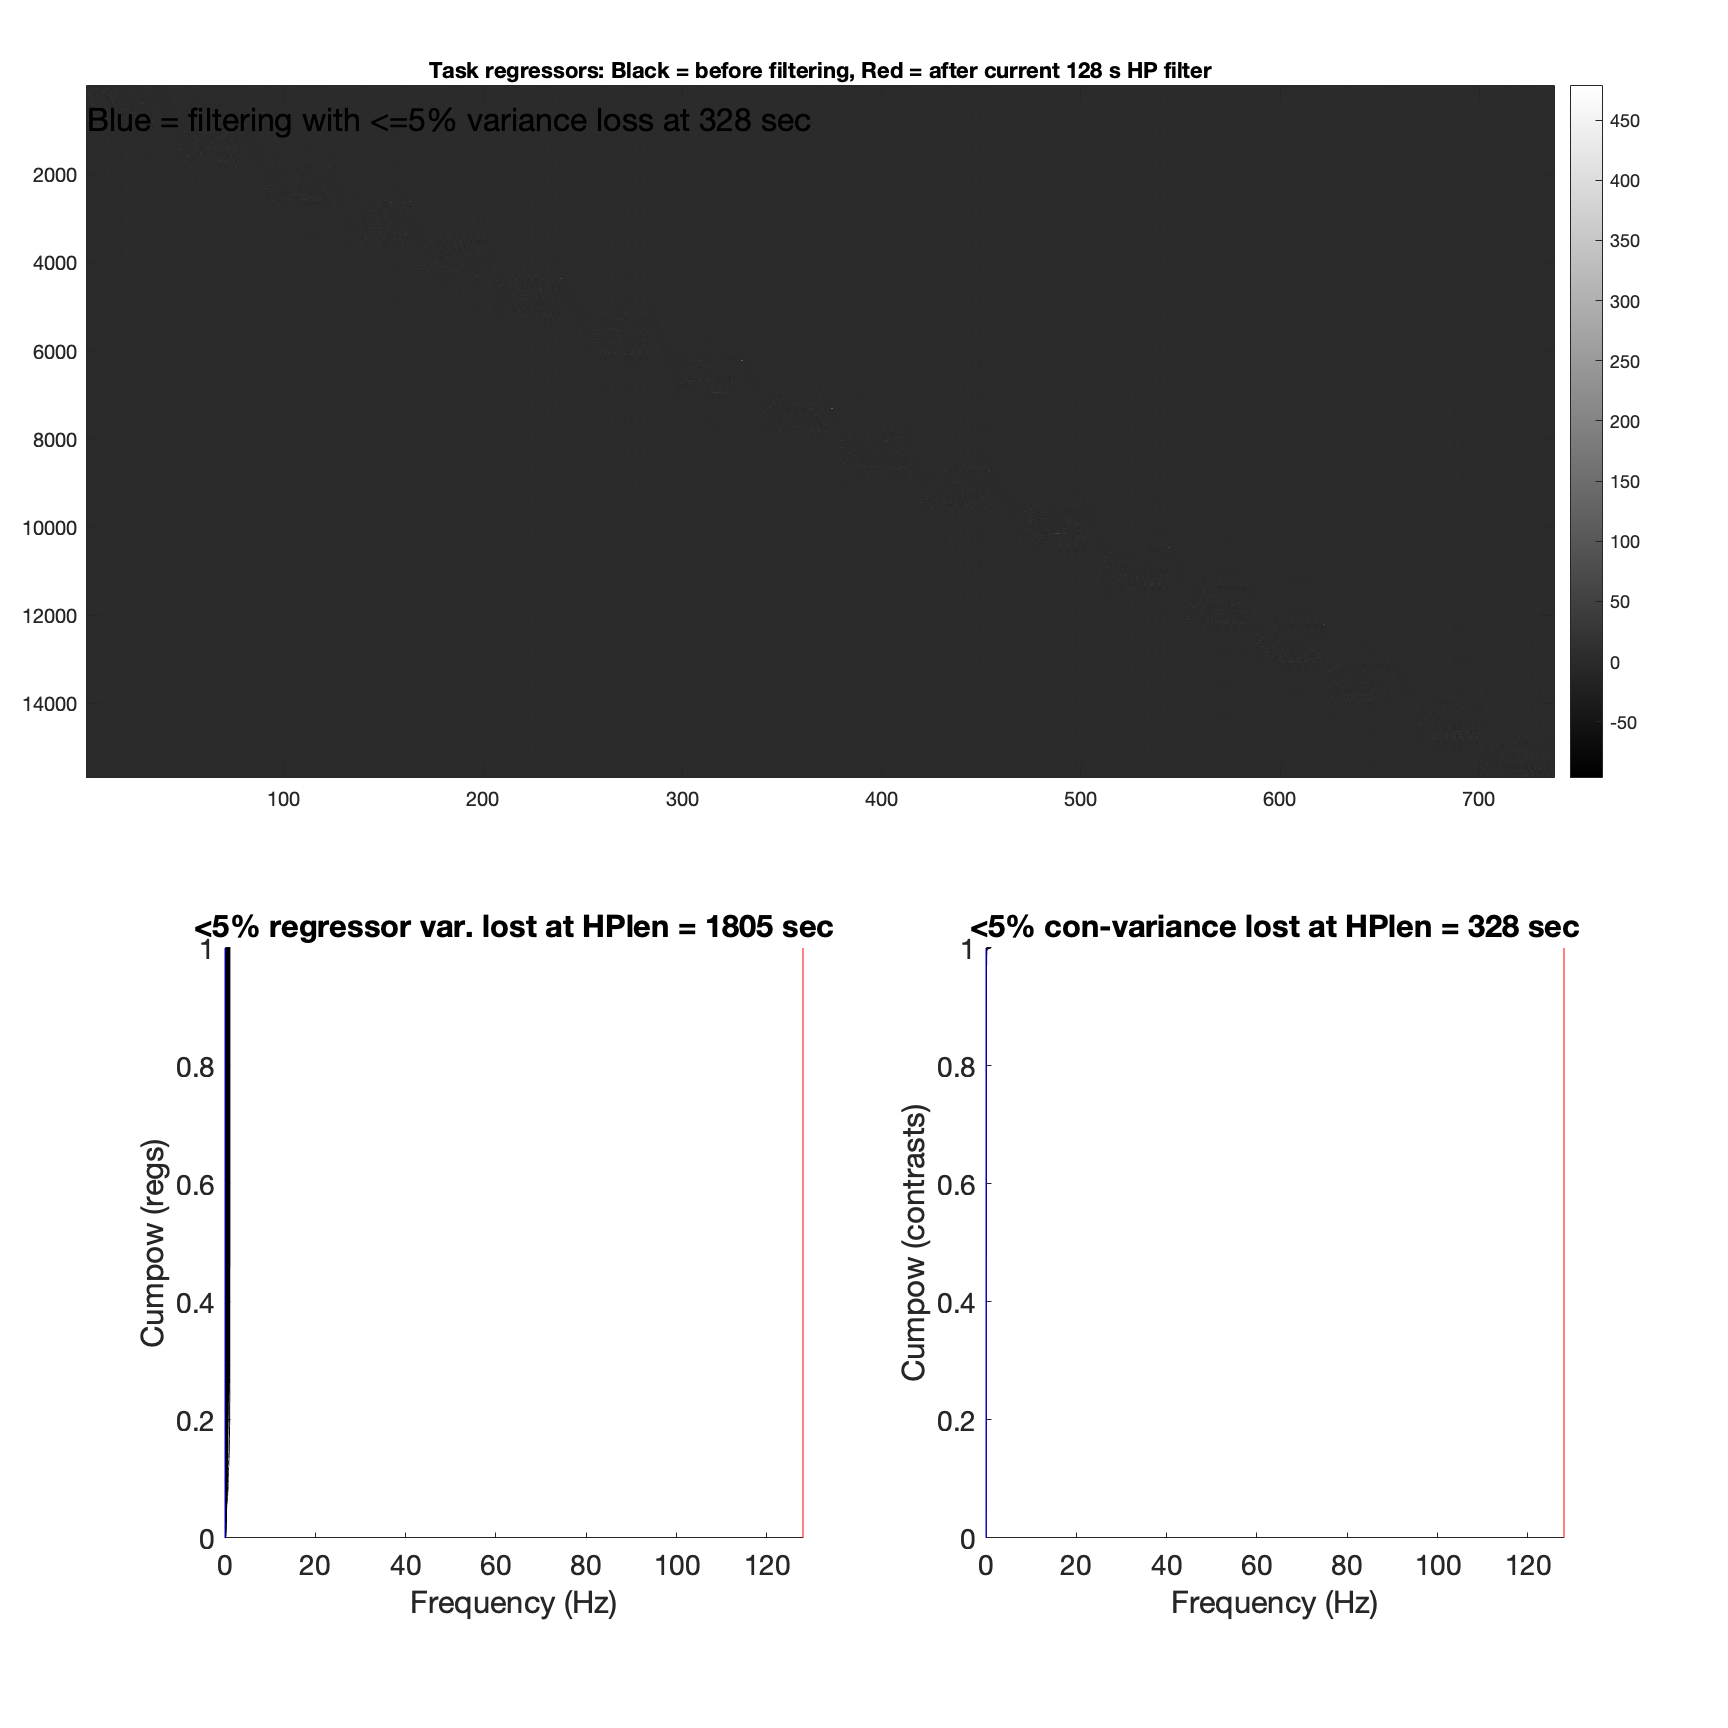

Saved High_pass_filter_analysis.png in SPM directory


%% 1. Check VIF for entire design matrix
out_all = scn_spm_design_check(fullfile(glm_dir, sub)); %'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel/sub-0078')

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.



VIFs greater than 1.300000e+00

    VIF   REGRESSOR
   1.35   reg0003: "Sn(1) cue-high_stim-low*bf(1)"
   1.47   reg0007: "Sn(1) CUE*bf(1)"
   1.55   reg0008: "Sn(1) EXPECT_RATING*bf(1)"
   1.45   reg0052: "Sn(2) CUE*bf(1)"
   1.46   reg0053: "Sn(2) EXPECT_RATING*bf(1)"
   1.55   reg0096: "Sn(3) CUE*bf(1)"
   1.72   reg0097: "Sn(3) EXPECT_RATING*bf(1)"
   1.69   reg0135: "Sn(4) CUE*bf(1)"
   1.71   reg0136: "Sn(4) EXPECT_RATING*bf(1)"
   1.48   reg0174: "Sn(5) CUE*bf(1)"
   1.46   reg0175: "Sn(5) EXPECT_RATING*bf(1)"
   1.60   reg0211: "Sn(6) CUE*bf(1)"
   1.65   reg0212: "Sn(6) EXPECT_RATING*bf(1)"
   1.63   reg0255: "Sn(7) CUE*bf(1)"
   1.74   reg0256: "Sn(7) EXPECT_RATING*bf(1)"
   1.65   reg0293: "Sn(8) cue-high_stim-high*bf(1)"
   1.68   reg0299: "Sn(8) CUE*bf(1)"
   1.68   reg0300: "Sn(8) EXPECT_RATING*bf(1)"
   1.59   reg0345: "Sn(9) CUE*bf(1)"
   1.56   reg0346: "Sn(9) EXPECT_RATING*bf(1)"
   1.61   reg0385: "Sn(10) CUE*bf(1)"
   1.68   reg0386: "Sn(10) EXPECT_RATING*bf(1)"
  

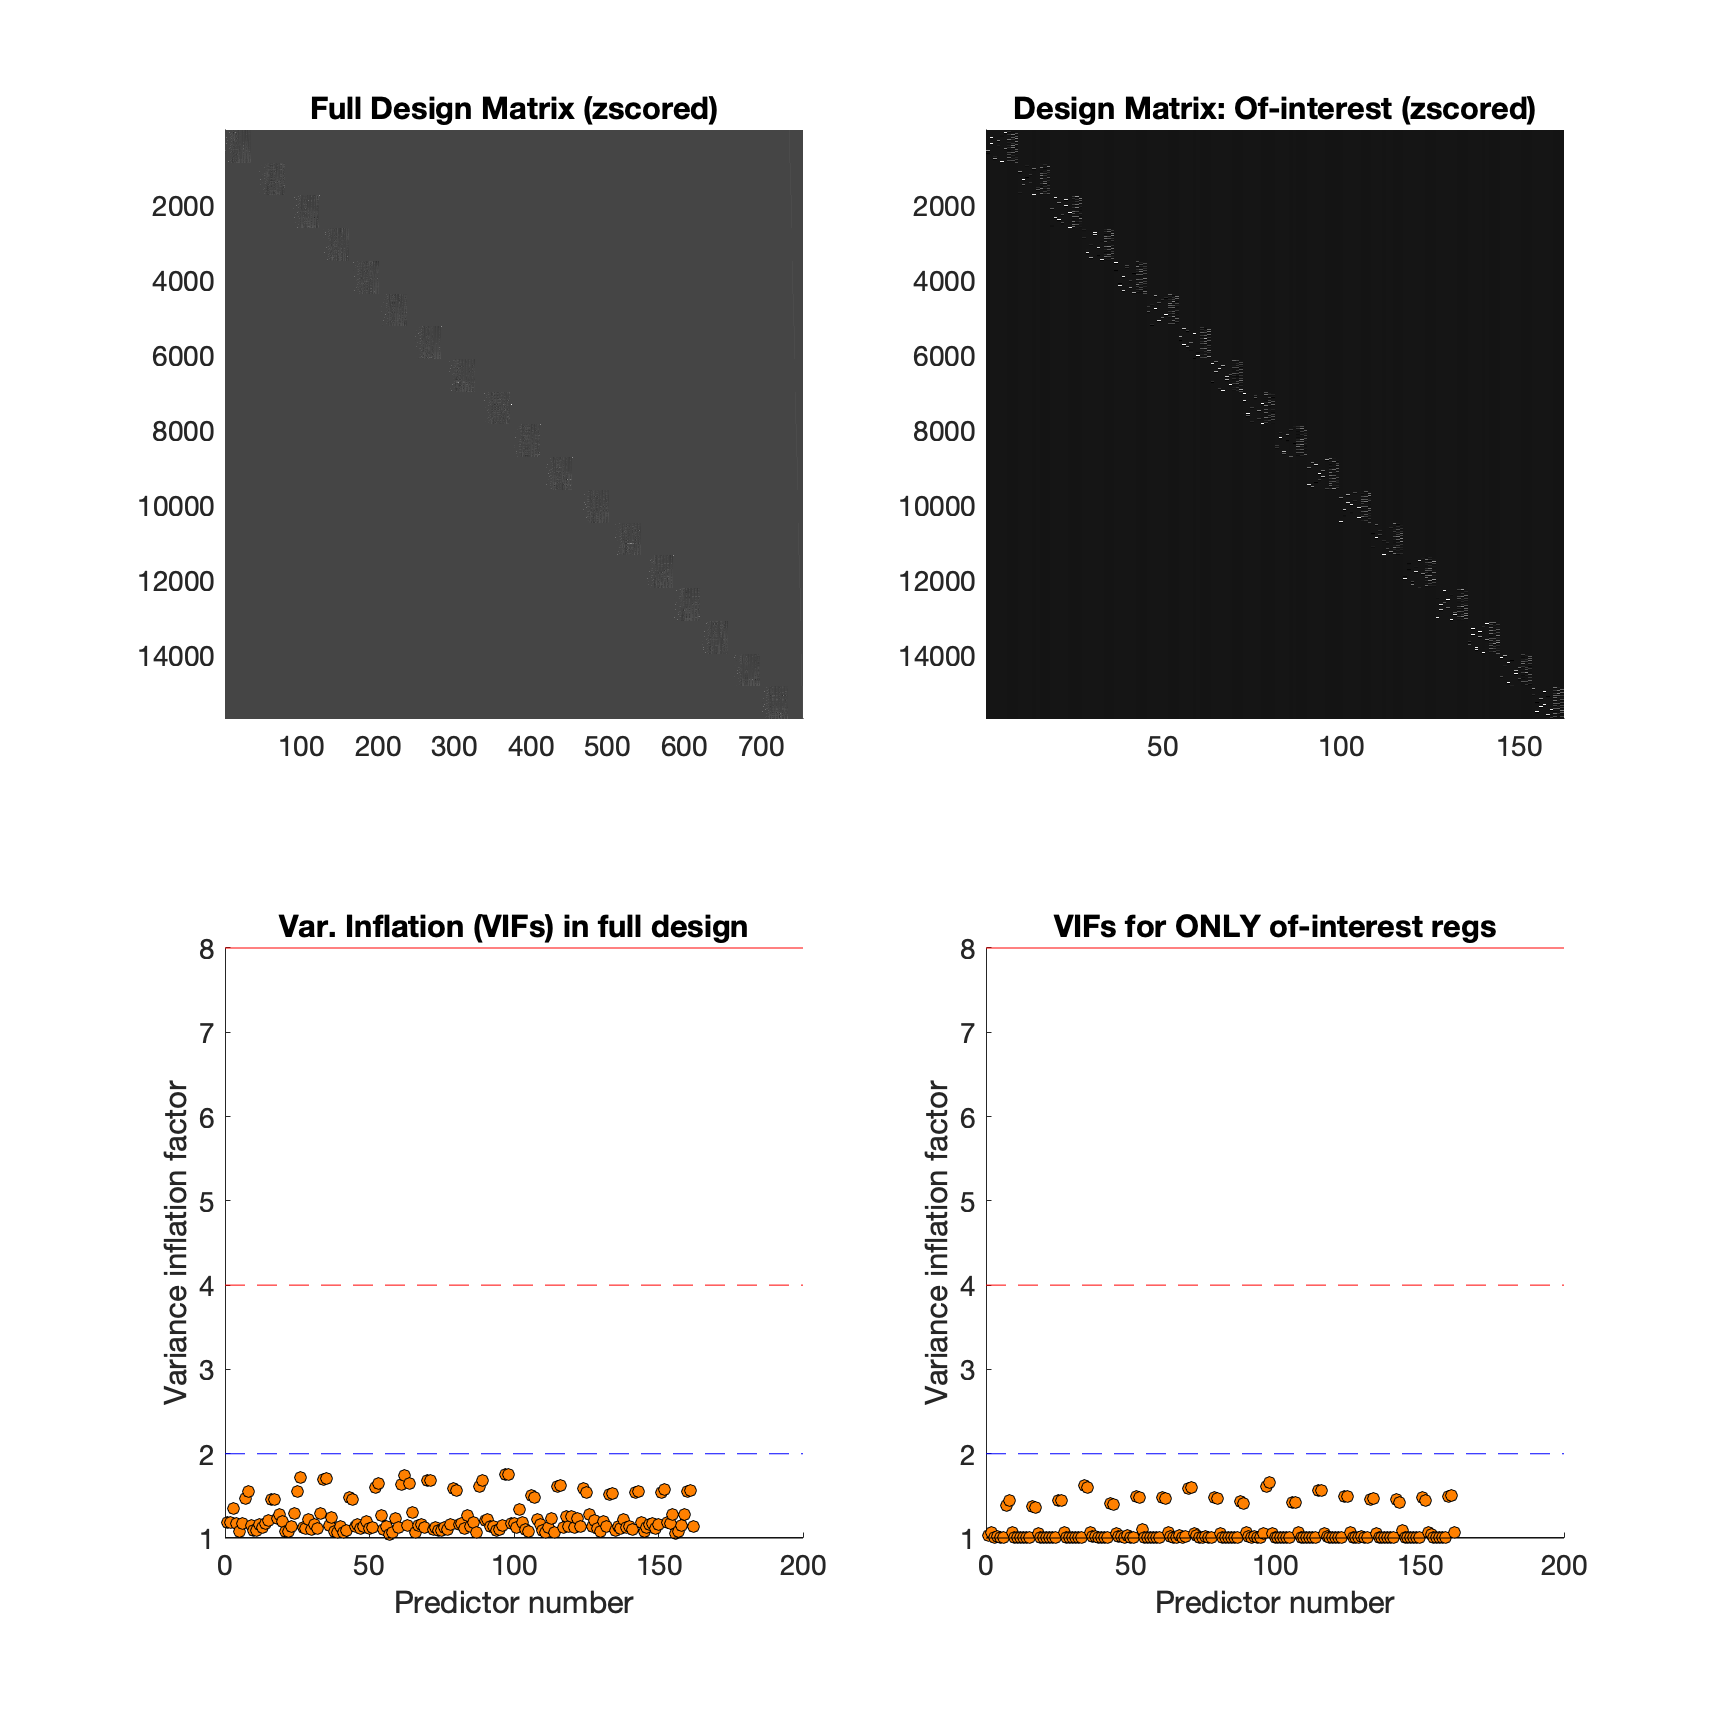

Saved Variance_Inflation.png in SPM directory


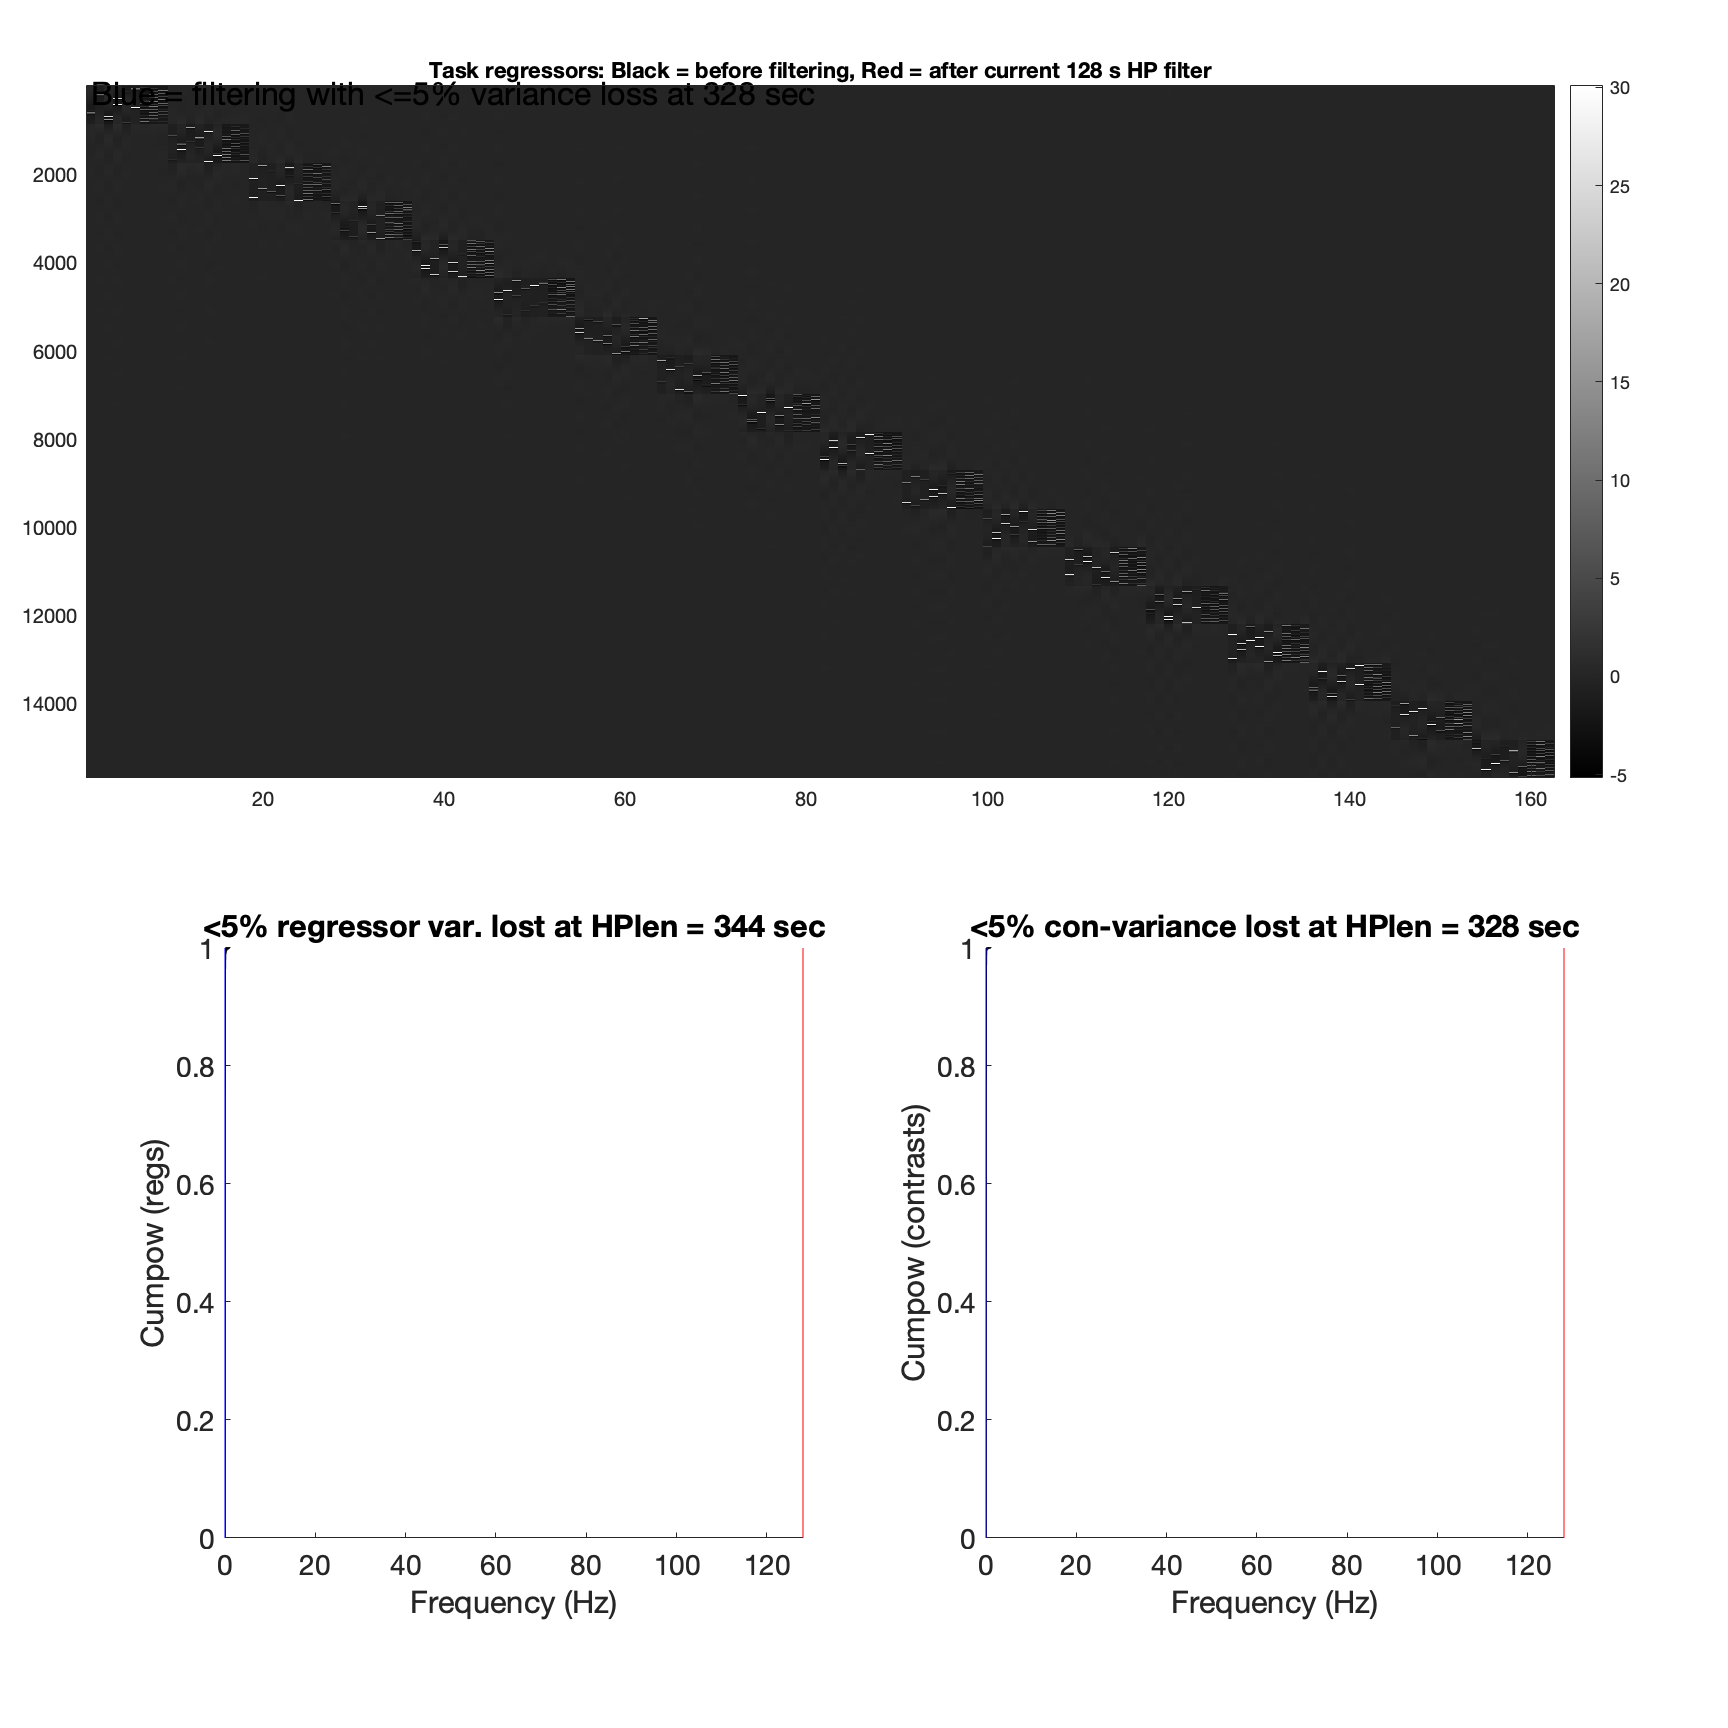

Saved High_pass_filter_analysis.png in SPM directory


out_eventonly = struct with fields:
    allvifs: [1×162 double]
       name: {1×162 cell}



%% 2. Check VIF for entire design matrix
out_eventonly = scn_spm_design_check(fullfile(glm_dir, sub), 'events_only' )%'/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel/sub-0078', 'events_only')


% VIF based on behavioral per run
%% figures: https://www.mathworks.com/matlabcentral/answers/516523-how-can-i-save-a-plot-to-a-variable-to-be-printed-later-i-m-more-specifically-referring-to-problem

%% 3. VIF per run _______________________________________________________
% identify how many runs in SPM
    % find nifti files
    niilist = dir(fullfile(smooth_dir, sub, '*/smooth-6mm_*task-cue*_bold.nii'));
    nT = struct2table(niilist); % convert the struct array to a table
    sortedT = sortrows(nT, 'name'); % sort the table by 'DOB'

    sortedT.sub_num(:) = str2double(extractBetween(sortedT.name, 'sub-', '_'));
    sortedT.ses_num(:) = str2double(extractBetween(sortedT.name, 'ses-', '_'));
    sortedT.run_num(:) = str2double(extractBetween(sortedT.name, 'run-', '_'));

    nii_col_names = sortedT.Properties.VariableNames;
    nii_num_colomn = nii_col_names(endsWith(nii_col_names, '_num'));
    onset_dir = fullfile(main_dir, 'data', 'fmri', 'fmri01_onset', 'onset02_SPM');
    % find onset files
    onsetlist = dir(fullfile(onset_dir, sub, '*', strcat(sub, '_*_task-cue_*_events.tsv')));
    onsetT = struct2table(onsetlist);
    sortedonsetT = sortrows(onsetT, 'name');

    sortedonsetT.sub_num(:) = str2double(extractBetween(sortedonsetT.name, 'sub-', '_'));
    sortedonsetT.ses_num(:) = str2double(extractBetween(sortedonsetT.name, 'ses-', '_'));
    sortedonsetT.run_num(:) = str2double(extractBetween(sortedonsetT.name, 'run-', '_'));

    onset_col_names = sortedonsetT.Properties.VariableNames;
    onset_num_colomn = onset_col_names(endsWith(onset_col_names, '_num'));
    disp(nii_num_colomn)

    {'sub_num'}    {'ses_num'}    {'run_num'}



    %intersection of nifti and onset files
    A = intersect(sortedT(:, nii_num_colomn), sortedonsetT(:, onset_num_colomn));

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


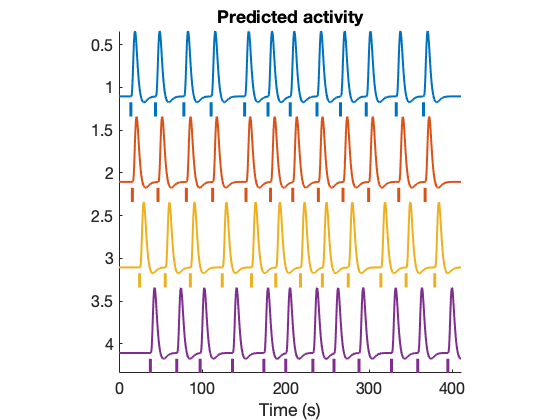

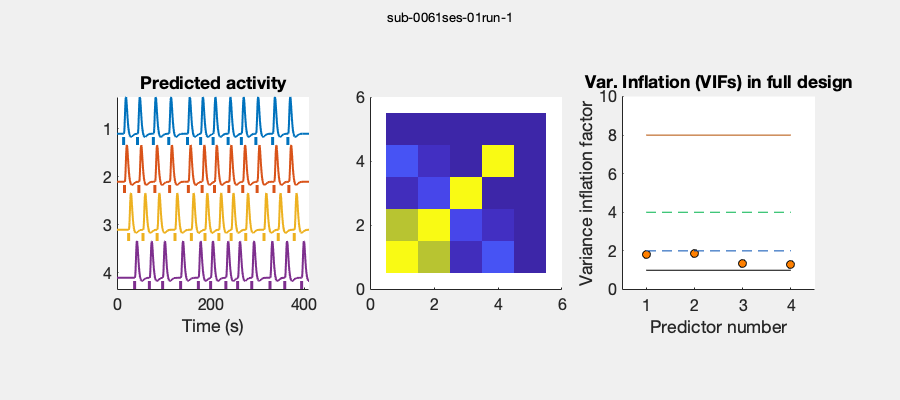

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


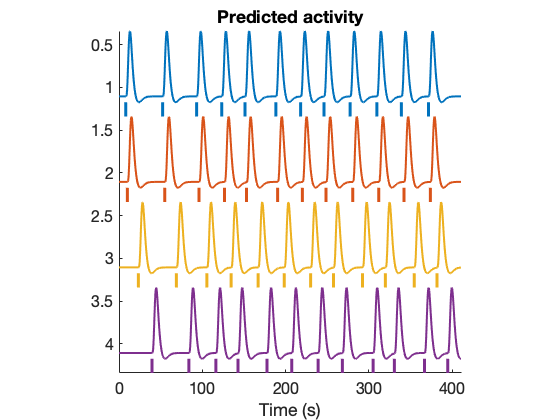

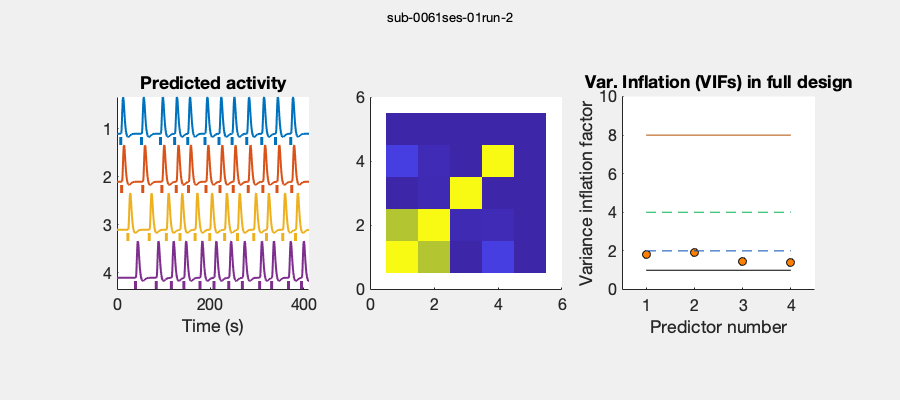

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


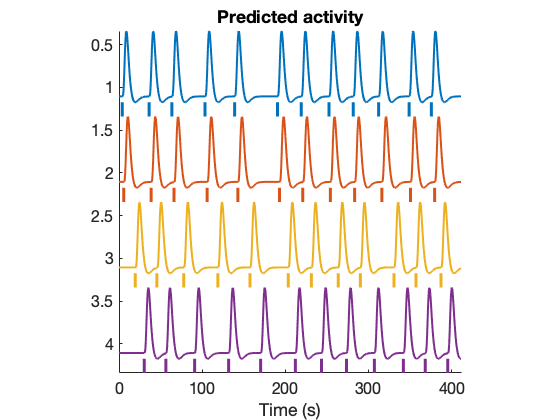

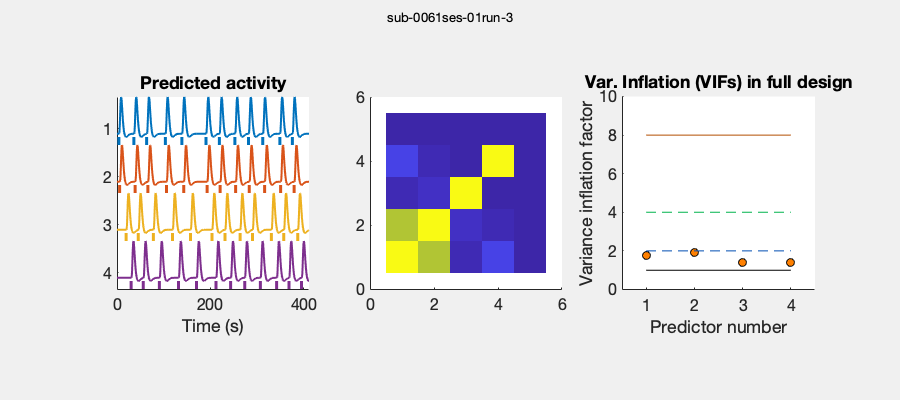

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


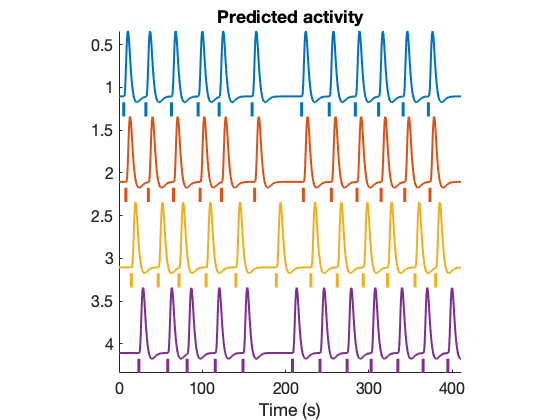

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


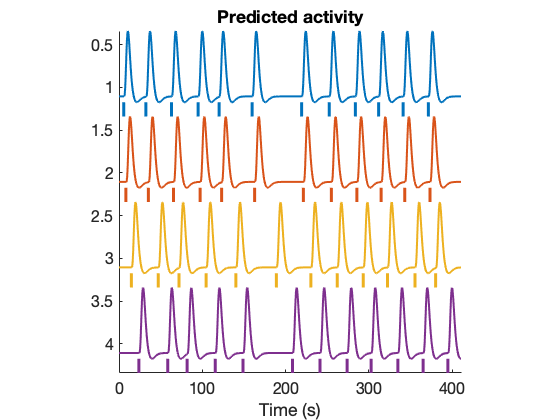

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


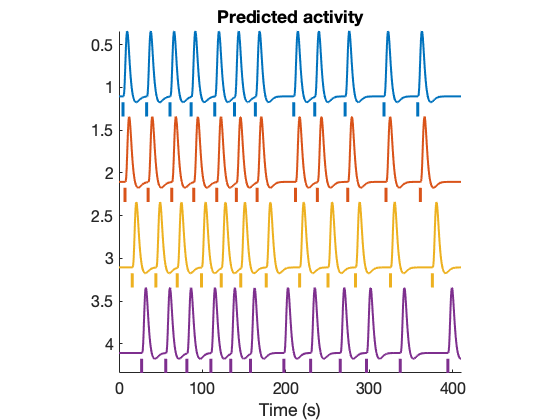

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


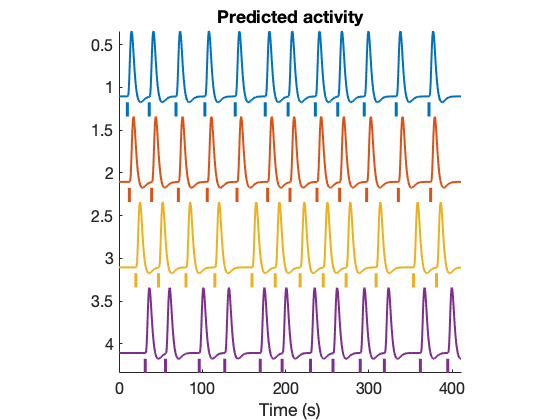

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


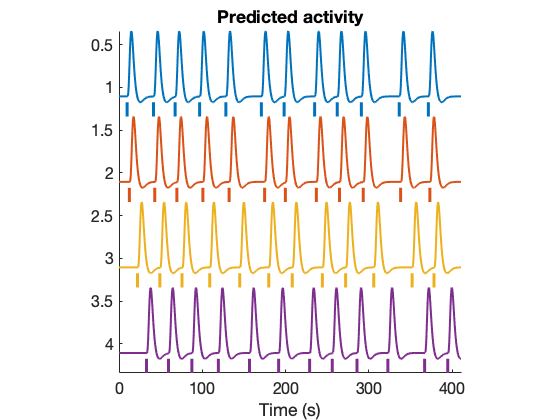

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


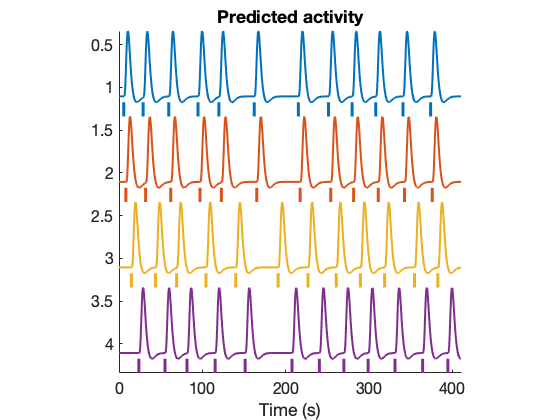

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


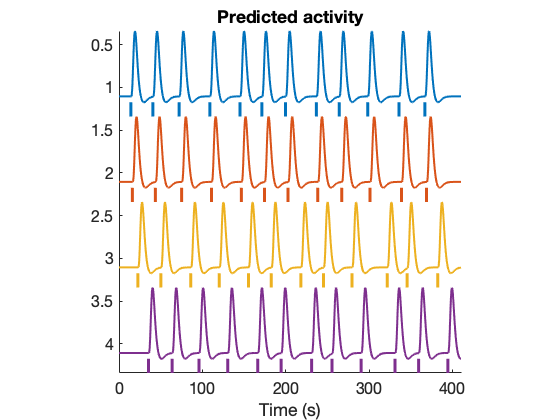

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


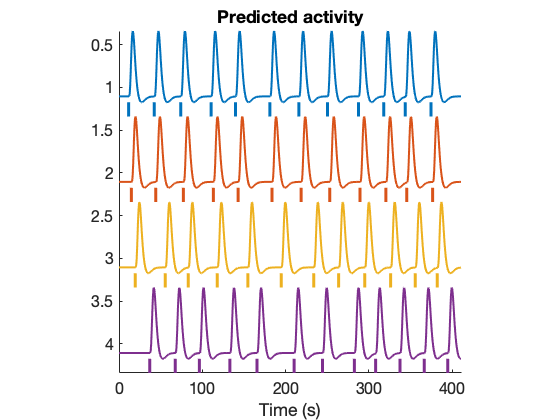

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


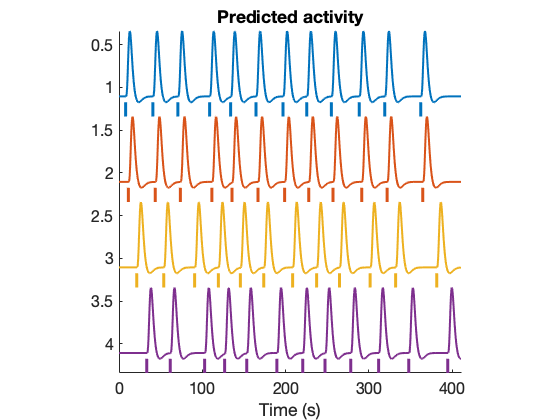

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


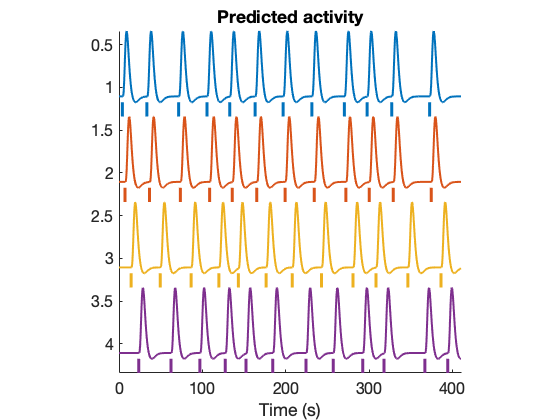

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


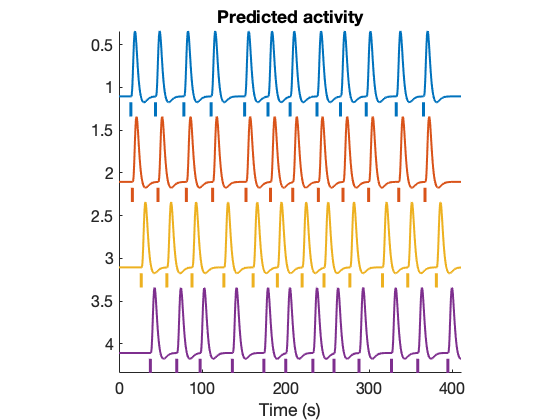

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


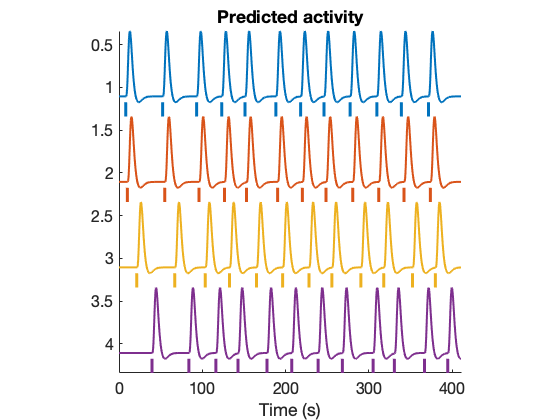

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


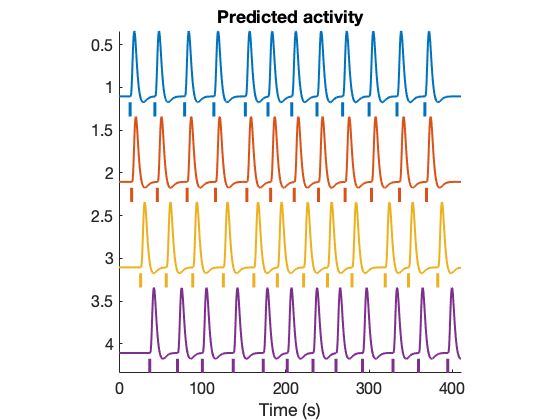

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


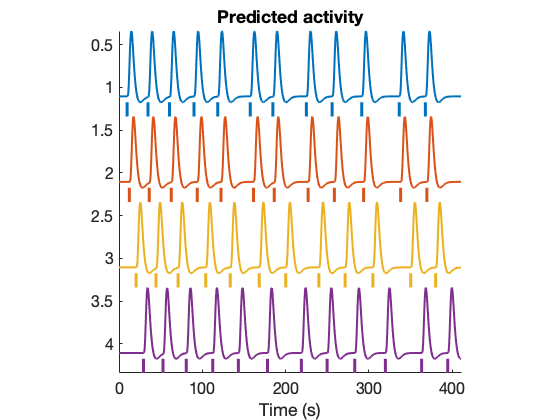

ans =   Figure (heat_map) with properties:

      Number: 7
        Name: 'heat_map'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (vifs) with properties:

      Number: 10
        Name: 'vifs'
       Color: [1 1 1]
    Position: [1001 559 560 420]
       Units: 'pixels'

  Show all properties


Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


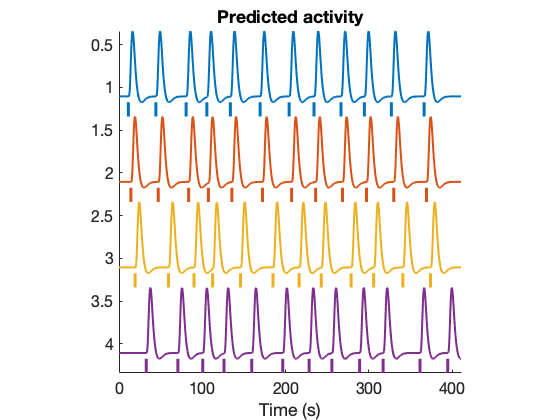

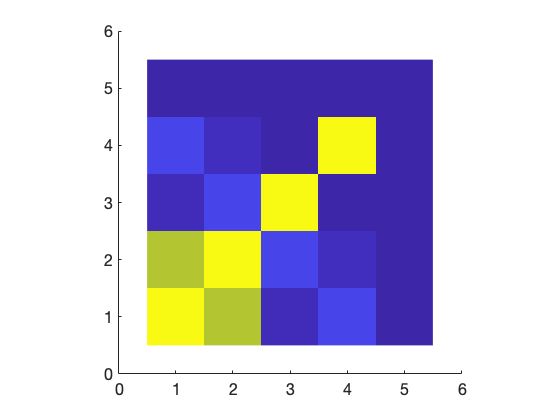

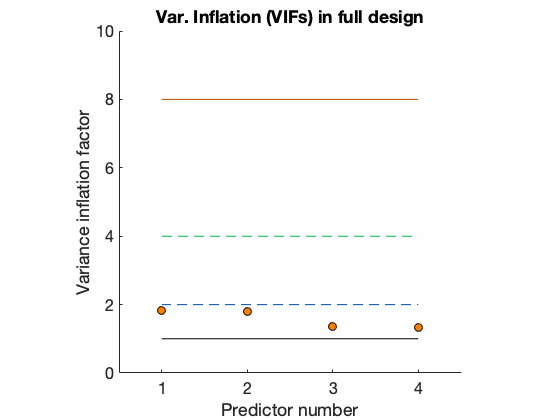


    for run_ind = 1:size(A, 1)

        sub = []; ses = []; run = [];
        sub = strcat('sub-', sprintf('%04d', A.sub_num(run_ind)));
        ses = strcat('ses-', sprintf('%02d', A.ses_num(run_ind)));
        run = strcat('run-', sprintf('%01d', A.run_num(run_ind)));

        %t = readtable('/Users/h/Dropbox (Dartmouth College)/projects_dropbox/d_beh/sub-0078/task-social/ses-01/sub-0078_ses-01_task-social_run-05-pain_beh');
        % h_stim = t(ismember(t.param_stimulus_type, 'high_stim'),:);
        % l_stim = t(ismember(t.param_stimulus_type, 'low_stim'),:);
        % m_stim = t(ismember(t.param_stimulus_type, 'med_stim'),:);
        onset_glob = dir(fullfile(onset_dir, sub, ses, strcat(sub, '_', ses, '_task-cue_', strcat('run-', sprintf('%02d', A.run_num(run_ind))), '*_events.tsv')));
        onset_fname = fullfile(char(onset_glob.folder), char(onset_glob.name));
        t = readtable(onset_fname, 'FileType','text');

%         onset01_cue = t.onset01_cue - t.param_trigger_onset;
%         onset02_expect = t.event02_expect_displayonset - t.param_trigger_onset;
%         onset03_stim = t.event03_stimulus_displayonset - t.param_trigger_onset;
%         onset04_actual = t.event04_actual_responseonset - t.param_trigger_onset;
        TR = 0.46;
        len = 872;
        onset_cell = {t.onset01_cue t.onset02_ratingexpect t.onset03_stim t.onset04_ratingoutcome };
        %plotDesign(onset_cell, 5, 0.46)
        %% separate plot:

        % subplot(1,3,1);grid on;
        figure('visible','off')
        X = onsets2fmridesign(onset_cell, TR, 872 .* TR, spm_hrf(1));
        plotdesignout = plotDesign(onset_cell,[], TR);
        pbaspect([1 1 1])
        ax1= gca;
        set(figure, 'visible', 'off')
        ax1.FontSize = 16; 
        % subplot(1,3,2); grid on;
        figure('visible','off')
        create_figure("heat_map")
        imagesc(corr(plotdesignout));
        pbaspect([1 1 1])
        ax2= gca;
        set(figure, 'visible', 'off')
        ax2.FontSize = 16; 
        % subplot(1,3,2)
        figure('visible','off')
        create_figure("vifs")
        vifs = getvif(X, false, 'plot');
        pbaspect([1 1 1])
        ax3 = gca;
        set(figure, 'visible', 'off')
        ax3.FontSize = 16; 

        %%
        %set(0,'DefaultFigureVisible','on')
        fnew = figure('Position', [10 10 900 400], 'visible', 'on');

        %axis tight; axis image; 
        ax1_copy = copyobj(ax1,fnew);
        subplot(1,3,1,ax1_copy)

        copies = copyobj(ax2,fnew);
        ax2_copy = copies(1);
        subplot(1,3,2,ax2_copy)

        copies2 = copyobj(ax3,fnew);
        ax3_copy = copies2(1);
        subplot(1,3,3,ax3_copy)

        sgtitle(strcat(sub, ses, run));

    end